clear; clc; close all;
disp("840 LCVR")

840 LCVR


%code paths
addpath("C:\Emily\AkkinLab\1300_System\emily_codes");
addpath(genpath("C:\Emily\AkkinLab\Shared_Codes"));
%output paths
Fpaths.disp_corr1="C:\Emily\AkkinLab\Outputs\Liquid_Crystal_Variable_Retarder_Orientation\NIR840_disp_corr_lcvr_AO1_ch1_07262026";
Fpaths.disp_corr2="C:\Emily\AkkinLab\Outputs\Liquid_Crystal_Variable_Retarder_Orientation\NIR840_disp_corr_lcvr_AO1_ch2_07262026";
Fpaths.calib_disp_corr1="C:\Emily\AkkinLab\Outputs\Liquid_Crystal_Variable_Retarder_Orientation\NIR840_calib_dispersion_correction_lcvr_AO1_ch1_07262026";
Fpaths.calib_disp_corr2="C:\Emily\AkkinLab\Outputs\Liquid_Crystal_Variable_Retarder_Orientation\NIR840_calib_dispersion_correction_lcvr_AO1_ch2_07262026";
Fpaths.shift_corr1="C:\Emily\AkkinLab\Outputs\Liquid_Crystal_Variable_Retarder_Orientation\NIR840_shift_corr_lcvr_AO1_ch1_07262026";
Fpaths.shift_corr2="C:\Emily\AkkinLab\Outputs\Liquid_Crystal_Variable_Retarder_Orientation\NIR840_shift_corr_lcvr_AO1_ch2_07262026";
Fpaths.calib_shift_corr1="C:\Emily\AkkinLab\Outputs\Liquid_Crystal_Variable_Retarder_Orientation\NIR840_calib_shift_corr_lcvr_AO1_ch1_07262026";
Fpaths.calib_shift_corr2="C:\Emily\AkkinLab\Outputs\Liquid_Crystal_Variable_Retarder_Orientation\NIR840_calib_shift_corr_lcvr_AO1_ch2_07262026";

%Parameters /  Data processing actions
% 1 = do the action; 0 = skip the action
Parameters.Start2=1025; %halfway point of system pixels 
Parameters.AutoPeakCorrCut = 0; %Cut low-frequency points to not see big dc offset
% Parameters.isCompressed = 0;

Parameters.zero_pad_before_interp = 1;
Parameters.interp_window_before_padding=0;
Parameters.interp_fit_method = "linear";
Parameters.InterpZeroPaddingFactor = 4; %Zero-padding factor for interpolation and for zero-padding the bscans

Parameters.CDPWindow = 1;
Parameters.Window=hamming(1024);

Parameters.dBlimit =0;
Parameters.weightedAO=1;
Parameters.calcAbsOrientation=1;

disp("LOADING INTERP PARAMS")

LOADING INTERP PARAMS


load("C:\Emily\AkkinLab\AkkinData\MariPenParameters\InterpParameters5.mat");
Parameters.Wavelengths_l= InterpParameters.Wavelengths_l;
Parameters.Wavelengths_r= InterpParameters.Wavelengths_r;
Parameters.InterpolatedWavelengths=InterpParameters.InterpolatedWavelengths;
Parameters.Ks=InterpParameters.Ks;
clear InterpParameters
% load("C:\Emily\AkkinLab\AkkinData\NIR840_lcvr_vary_ao_07012026\NIR840_interpolatedwavelengths5_parameters.mat", 'Wavelengths_l','Wavelengths_r','InterpolatedWavelengths','Ks');
% Parameters.Wavelengths_l= Wavelengths_l;
% Parameters.Wavelengths_r= Wavelengths_r;
% Parameters.InterpolatedWavelengths=InterpolatedWavelengths;
% Parameters.Ks=Ks;
% clear Wavelengths_l Wavelengths_r InterpolatedWavelengths Ks

Parameters.dispersion_L = 32;
Parameters.dispersion_polyfit_order=9;
Parameters.Approx_calib_loc = [290 310];
main_dispersion_peak_search_range = [20 Parameters.Approx_calib_loc(1)];
main_shift_peak_search_range=[70 80; 140 160];

num_blines_to_use = 10;
num_rotations_to_use = 7;
rotation_names = (["n30xg", "n20xg", "n10xg", "0xg", "10xg", "20xg", "30xg"]);
rotation_values_expected = [60 70 80 90 100 110 120];

%% Seven rotations, for each rotation load 1 buffer file
disp("LOADING BSCANS...")

LOADING BSCANS...


for ii_rotation=1:num_rotations_to_use
for ii_depth = 1:2
file_loc = sprintf("C:\\Emily\\AkkinLab\\AkkinData\\NIR840_lcvr_vary_ao_07012026\\LCVR_840_AO_D%d_%d.dat",ii_depth,ii_rotation);
[Bscans_temp,~,~] = BMOL_read_Bscans(file_loc);
Bscans1{ii_rotation}(:,:,:,ii_depth)=Bscans_temp(1:Parameters.Start2-1,:,:,:);
Bscans2{ii_rotation}(:,:,:,ii_depth)=Bscans_temp(Parameters.Start2:end,:,:,:);
end
end
clear file_loc Bscans_temp

%% load or calculate reference only, subtract from Bscans
%from https://drive.google.com/drive/folders/1_jx3DHg3HQeaoegpwik054d2qTAy26yg?usp=drive_link
disp("LOADING BG")

LOADING BG


Ref_only_file_loc = compose("C:\\Emily\\AkkinLab\\AkkinData\\NIR840_lcvr_vary_ao_07012026\\840 BG and CalibOnly\\LCR_BG_1_840_%g.dat",1:100);
[Ref_only_bscans_temp,~,~] = BMOL_read_Bscans(Ref_only_file_loc);
Ref_only_bscans_temp=mean(Ref_only_bscans_temp,[2,3]);
Ref_only_ch1=Ref_only_bscans_temp(1:Parameters.Start2-1,:,:,:);
Ref_only_ch2=Ref_only_bscans_temp(Parameters.Start2:end,:,:,:);

%check Ref only
disp("REF ONLY: APPLYING INTERP AND CALCULATING INITIAL CDP")

REF ONLY: APPLYING INTERP AND CALCULATING INITIAL CDP


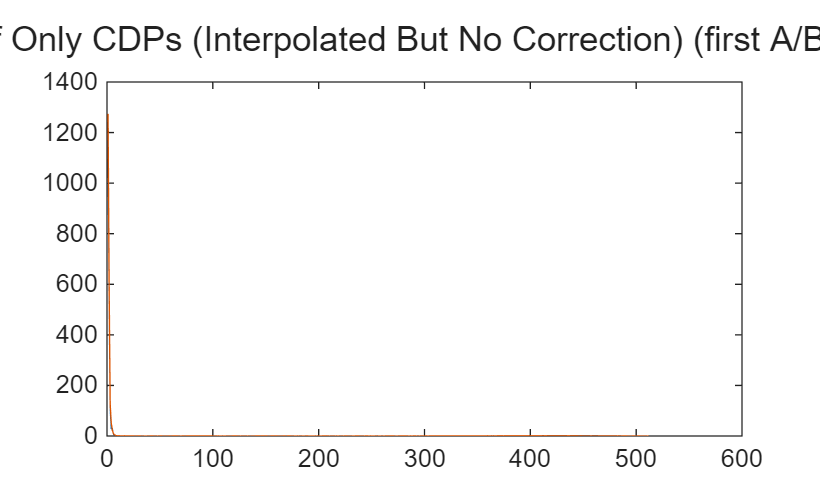

Ref_only_ch1_bscans{1} = Ref_only_ch1;
Ref_only_ch2_bscans{1} = Ref_only_ch2;
for ii_rotation = 1% :num_rotations_to_use
for ii_bline=1:1
    [Ch1_Ref_Interpolated{ii_rotation}(:,:,ii_bline,:) Ch2_Ref_Interpolated{ii_rotation}(:,:,ii_bline,:)]=BMOL_apply_interp(Ref_only_ch1_bscans{ii_rotation}(:,:,ii_bline,:), Ref_only_ch2_bscans{ii_rotation}(:,:,ii_bline,:), Parameters);
    Parameters.dispersionComp = 0;
    Parameters.toggle_shift_correction = 0;    
    Parameters.CDPZeroPaddingFactor = 1;
    [CDP1_Ref_Interpolated{ii_rotation}(:,:,ii_bline,:) CDP2_Ref_Interpolated{ii_rotation}(:,:,ii_bline,:)] = BMOL_calculate_cdp(Ch1_Ref_Interpolated{ii_rotation}(:,:,ii_bline,:),Ch2_Ref_Interpolated{ii_rotation}(:,:,ii_bline,:), Parameters, "main");
end
end
% show the CDPs initially
f_cdps = figure;
t_cdps = tiledlayout(f_cdps,1,1);
for ii_rotation = 1 %:num_rotations_to_use
    nexttile(t_cdps,ii_rotation);
    plot(abs(CDP1_Ref_Interpolated{ii_rotation}(:,1,1,1)),"DisplayName","Ch1 depth1"); hold on;
    plot(abs(CDP2_Ref_Interpolated{ii_rotation}(:,1,1,1)),"DisplayName","Ch2 depth1"); axis normal; hold off;
    % nexttile(t_cdps,ii_rotation+1);
    % plot(abs(CDP1_Ref_Interpolated{ii_rotation}(:,1,1,2)),"DisplayName","Ch1 depth2"); hold on; 
    % plot(abs(CDP2_Ref_Interpolated{ii_rotation}(:,1,1,2)),"DisplayName","Ch2 depth2"); axis normal; hold off;
end
sgtitle("Ref Only CDPs (Interpolated But No Correction) (first A/B line)")


% for ii_rotation = 1:7
%         Bscans1{ii_rotation}(:,:,1:num_blines_to_use,:) = Bscans1{ii_rotation}(:,:,1:num_blines_to_use,:) - Ref_only_ch1;
%         Bscans2{ii_rotation}(:,:,1:num_blines_to_use,:) = Bscans2{ii_rotation}(:,:,1:num_blines_to_use,:) - Ref_only_ch2;
% end
clear BG Ref_only Ref_only_ch1 Ref_only_ch2 Ref_only_ch1_bscans Ref_only_ch2_bscans

% %% If using precomputed DispComp / Shift
% % Load in MariPen's dispcomp precalculated main and calib files - use *-1 when forming PhaseCorrection to make ifft compatible
% Parameter_directory = 'C:\Emily\AkkinLab\AkkinData\NIR840_lcvr_vary_ao_07012026';
% dispcompfile1 = fullfile(Parameter_directory, 'NIR840_MariPen_DispComp_LCVR_ch1.dat'); %includes both dispcomp and shift
% fid1 = fopen(dispcompfile1,'r');
% angledisp1 = fread(fid1,1024,'real*8');
% fclose(fid1);
% MariPenParameters.PhaseCorrection1 = exp(-1i.*angledisp1*-1);
% 
% dispcompfile2 = fullfile(Parameter_directory, 'NIR840_MariPen_DispComp_LCVR_ch2.dat'); %includes both dispcomp and shift
% fid2 = fopen(dispcompfile2,'r');
% angledisp2 = fread(fid2,1024,'real*8');
% fclose(fid2);
% MariPenParameters.PhaseCorrection2 = exp(-1i.*angledisp2*-1);
% 
% % Uncomment to use the parameters above
% % Parameters.PhaseCorrection1 = MariPenParameters.PhaseCorrection1;
% % Parameters.PhaseCorrection2 = MariPenParameters.PhaseCorrection2;
% % % Parameters.CalibPhaseCorrection1 = MariPenParameters.CalibPhaseCorrection1;
% % % Parameters.CalibPhaseCorrection2 = MariPenParameters.CalibPhaseCorrection2;
% % Parameters.ShiftCorrection1 = 1;
% % Parameters.ShiftCorrection2 = 1;
% % % Parameters.CalibShiftCorrection1 = 1;
% % % Parameters.CalibShiftCorrection2 = 1;

## Process

% check_lcvr_axis_orientation(Bscans1, Bscans2, main_dispersion_peak_search_range, main_shift_peak_search_range, num_rotations_to_use, num_blines_to_use, rotation_names, rotation_values_expected, Fpaths, Parameters)